%% #2 Boundary value problem with shooting method Chapra 22.3 linear 2nd-order ODEs
%use shooting method.  Two guesses of zb1, zb2 to get right-side yb1, yb2
%then compute zb from linear interpolation
%finally, solve the problem with correct zb
tspan=0:.1:20;
zb1=0  ;
zb2=-1.0  ; %two guesses of dy/dx, use anything between 0 and -1.0
[x,y]=ode45(   @func, tspan, [5, zb1]                  );%first shot    
yb1=y(    end, 1        )%result of first shot

yb1 =      5.773624759430724e+04

[x,y]=ode45(   @func, tspan, [5, zb2]                  );%second shot
yb2=y(    end, 1         )%result of 2nd shot

yb2 =     -1.193586303612834e+04

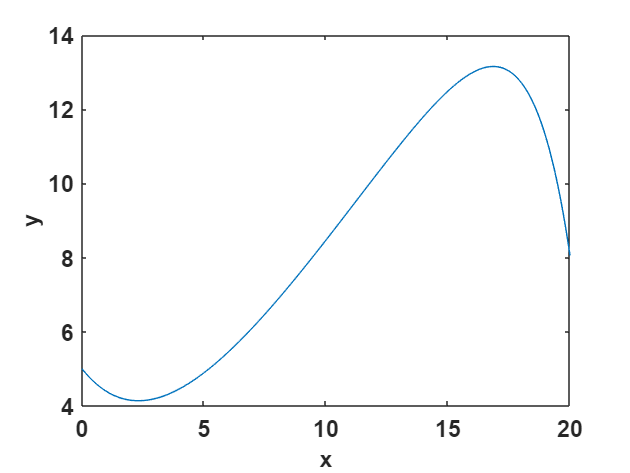

zb=interp1(   [yb1, yb2], [zb1, zb2],       8,      'pchip'); %linear interpolation to get zb
[x,y]=ode45(   @func, tspan, [5, zb]            );%solution using      zb

%% Output
figure 
plot(x, y(:, 1)    ) %plot the y only, so must choose the correct column
hold on
set(gca, 'fontsize',14,'fontweight','bold');
ylabel('y','fontsize',14,'fontweight','bold')
xlabel('x','fontsize',14,'fontweight','bold')

k6=find(abs(x(:,1)-6)<1e-6);%k6=index when x=6
yshoot6=y(k6,1)

yshoot6 =    5.455688314381552

k16=find(abs(x(:,1)-16)<1e-6);%k5=index when x=16
yshoot16=y(k16,1)

yshoot16 =   12.987620629404361


%% function

function dy = func( x,y ) %Can replace "func" with any name
%Chapra Problem 22.3
%   Use shooting method to solve 2 linear ODEs
dy=[   y(2)    ;   ( 2*y(2)+y(1)-x  )/7      ]; %single line form (alternatively can write 2 lines)
end
